clear
Q=importdata('test2.txt')

Q = 	1.0e+04 *

    0.0010   -0.0000
    0.0019   -0.0000
    0.0030   -0.0000
    0.0039   -0.0000
    0.0050   -0.0000
    0.0060   -0.0000
    0.0069   -0.0000
    0.0079   -0.0000
    0.0090   -0.0000
    0.0100   -0.0000


%Søjle 1 tid i ms 
%Søjle 2 vinkel af header i grade
V=importdata('test2_data')

V = struct with fields:
          data: [1747×4 double]
      textdata: {2×4 cell}
    colheaders: {'t'  'x'  'y'  'θ_{r}'}


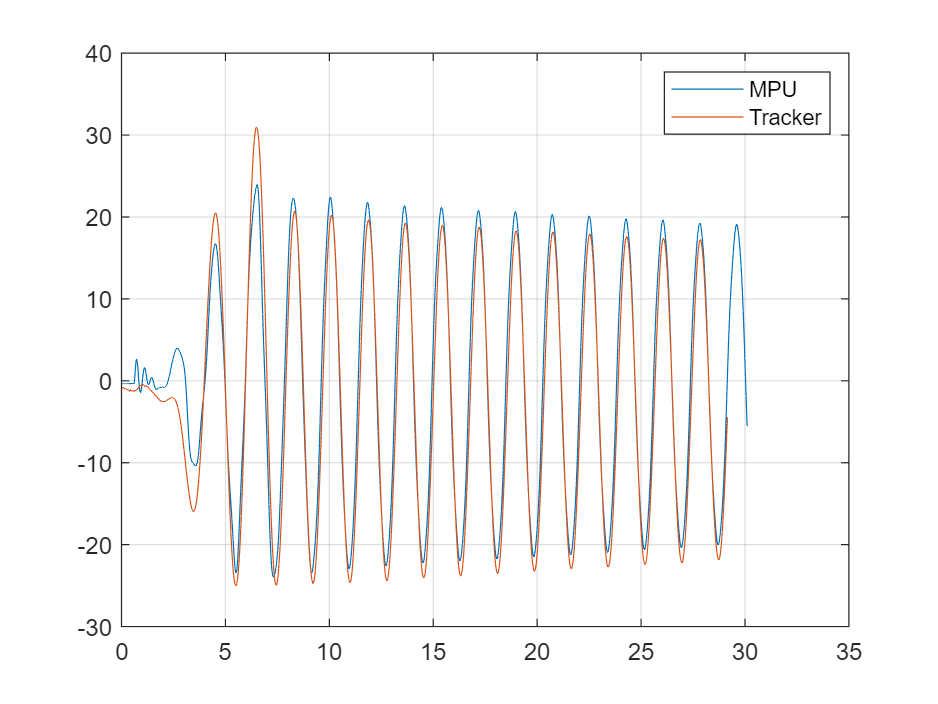

% Søjle 1 (tid) og 4(vinkel) i V der er vigtigt
%Rået plot af de to værdier samlet:
close all hidden
plot(Q(:,1)/1000,Q(:,2))
grid on
hold on 

plot(V.data(:,1),V.data(:,4)+90)
grid on 
legend('MPU','Tracker')
hold off 

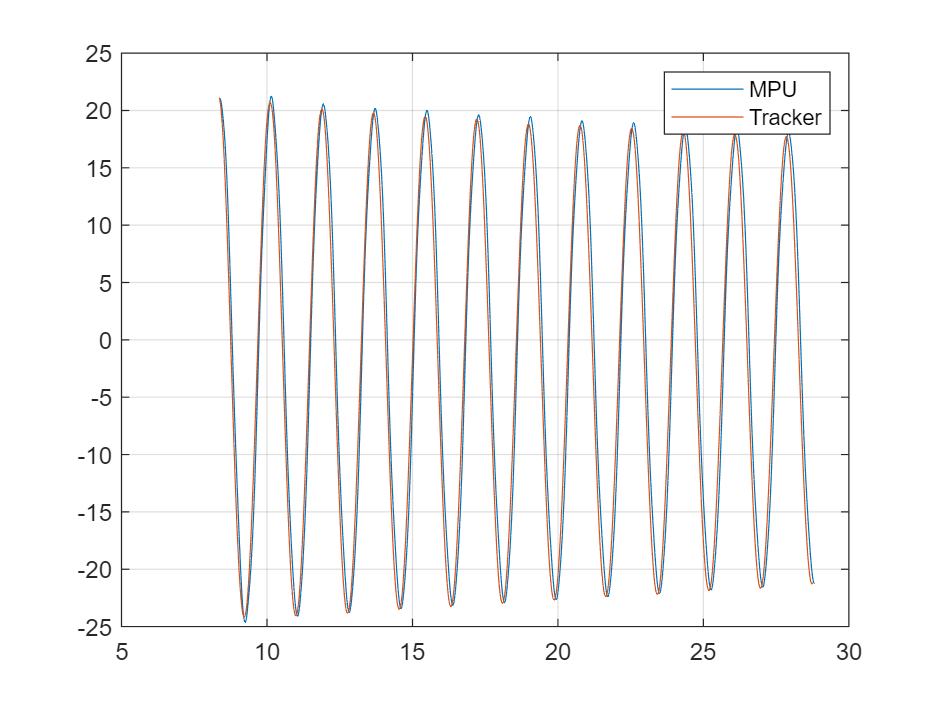

%Plottet samlet data
close all hidden
plot(Q(826:2871,1)/1000+0.1,Q(826:2871,2)-1.186)
grid on
hold on 

plot(V.data(500:1724,1),V.data(500:1724,4)+90.54)
grid on 
legend('MPU','Tracker')
hold off 

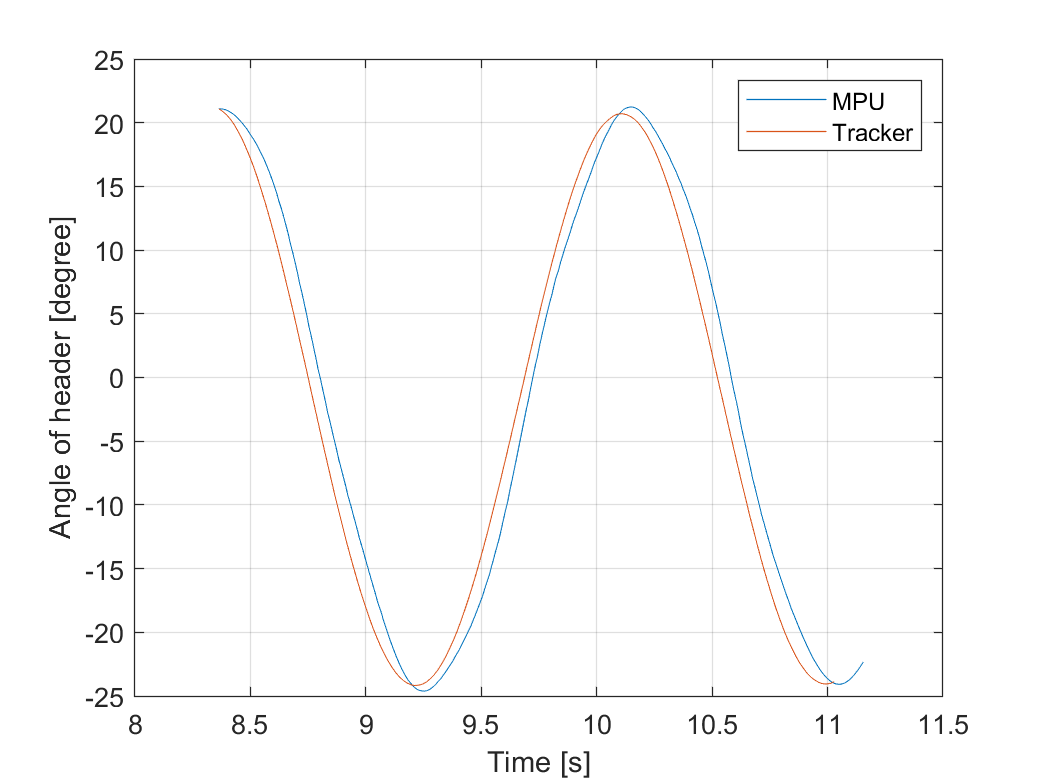

%close all hidden
%Match i tid og værdi
plot(Q(826:1105,1)/1000+0.1,Q(826:1105,2)-1.186)
grid on
hold on 

plot(V.data(500:659,1),V.data(500:659,4)+90.54)
grid on 
legend('MPU','Tracker')
xlabel('Time [s]')
ylabel('Angle of header [degree]')
hold off 

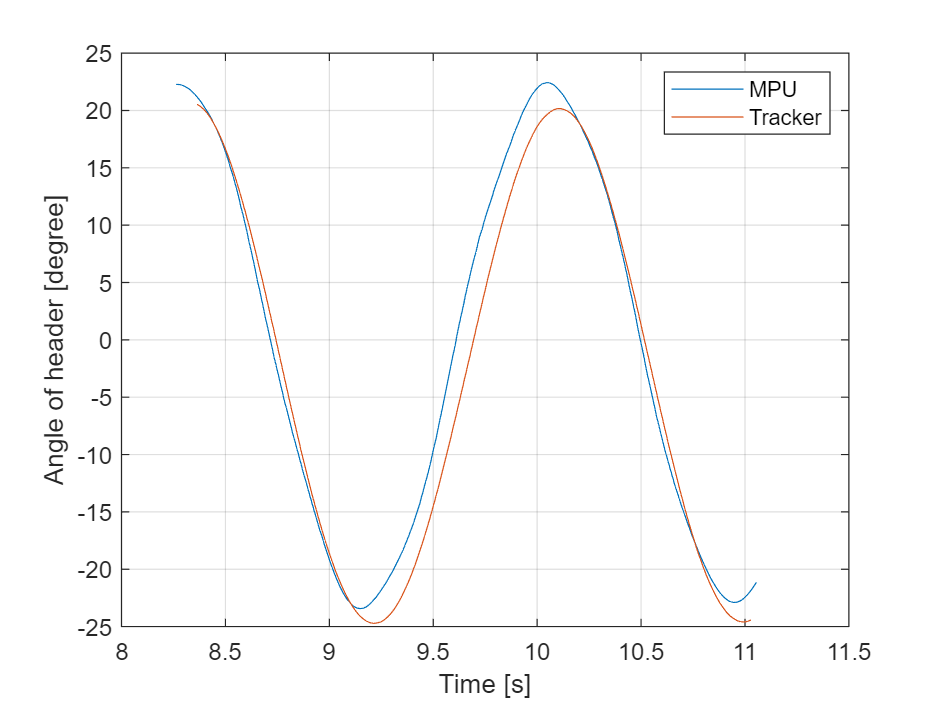

%Overhovedet ikke matchtet
plot(Q(826:1105,1)/1000,Q(826:1105,2))
grid on
hold on 

plot(V.data(500:659,1),V.data(500:659,4)+90)
grid on 
legend('MPU','Tracker')
xlabel('Time [s]')
ylabel('Angle of header [degree]')
hold off 

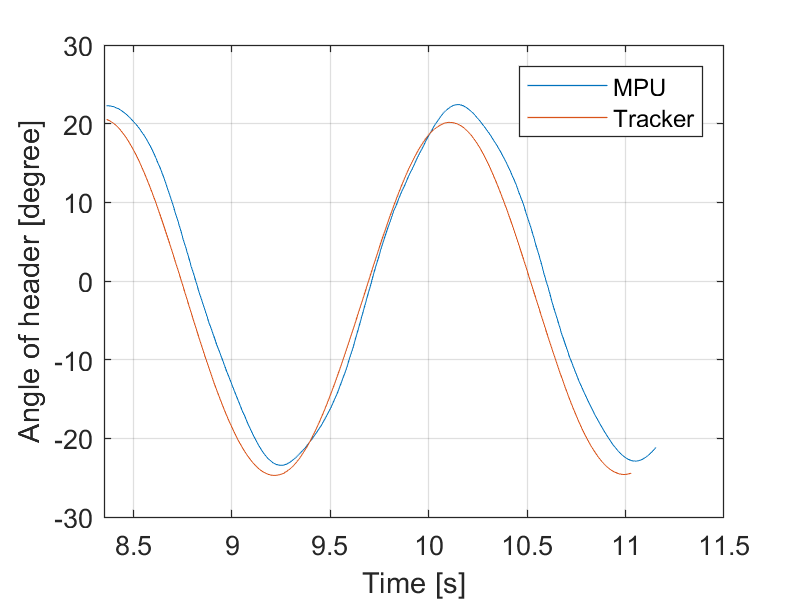

%Match i tid og ikke i værdi
plot(Q(826:1105,1)/1000+0.1,Q(826:1105,2))
grid on
hold on 

plot(V.data(500:659,1),V.data(500:659,4)+90)
grid on 
legend('MPU','Tracker','location','northeast')
xlabel('Time [s]')
ylabel('Angle of header [degree]')
hold off 
xlim([8.35,11.4])

x0=0;
y0=0;
plotwidth=400;
height=300;
set(gcf,'position',[x0,y0,plotwidth,height])
exportgraphics(gcf,'angle_test_app1.pdf','ContentType','vector')

B=importdata('test2_data')

B = struct with fields:
          data: [1747×4 double]
      textdata: {2×4 cell}
    colheaders: {'t'  'x'  'y'  'θ_{r}'}


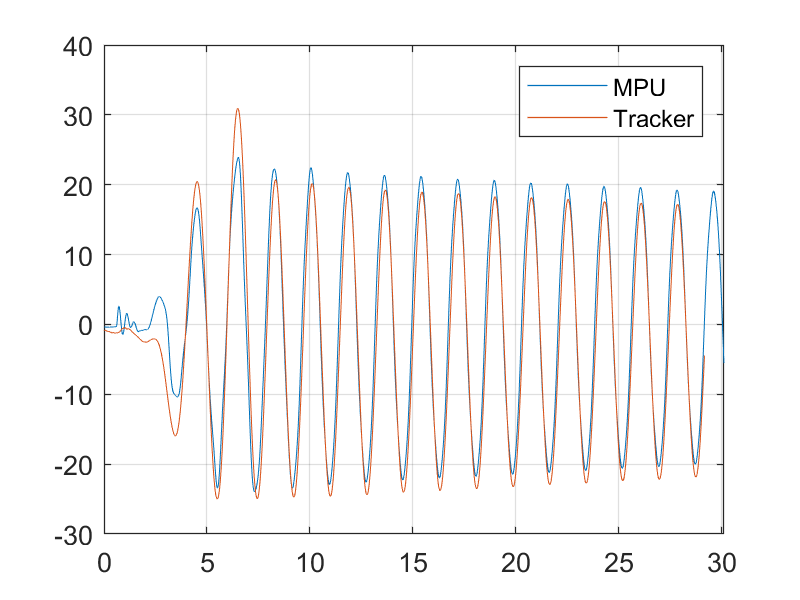


plot(Q(:,1)/1000,Q(:,2))
grid on
hold on 

plot(B.data(:,1),B.data(:,4)+90)
grid on 
legend('MPU','Tracker')
hold off 